# Numerisches Rechnen mit MATLAB

Der Kern von MATLAB ist das Matrix-Labor. Daher werden wir uns in dieser Vorlesung mit Vektoren, Matrizen und linearer Algebra beschäftigen.

## Vektoren

Zur Erinnerung: Ein eindimensionales Array (oder mathematisch formuliert ein Vektor) wird mit eckigen Klammern `[ ] `erzeugt. Der Zugriff erfolgt danach aber mit runden Klammern `( )`. 

A = [2, -37.8, 17, 8];
A

A(2)

Verwenden wir das Komma zur Trennung der einzelnen Zahlen, so erzeugen wir eine Zeile mit vier Spalten. Benutzen wir jedoch den Strichpunkt/das Semikolon, so erhalten wir vier Zeilen und eine Spalte:

B = [2; 4; 6; 8];
B

Mathematisch gesehen ist das erste Objekt ein Zeilenvektor, das zweite Objekt ein Spaltenvektor. 

Mit Vektoren gleicher Größe können wir ganz normal rechnen:

x = [-2.3, 4.3, 5.0];
y = [3.8, -0.1, 2.2];

x+y

Haben die beiden Arrays/Vektoren nicht die gleiche Dimension, so erhalten wir eine Fehlermeldung:

x = [-2.3, 4.3, 5.0];
y = [3.8, -0.1, 2.2, 3.2];

%x+y

Das ganze funktioniert auch als Spaltenvektoren bzw. auch mit Subtraktion:

x = [-2.3; 4.3; 5.0];
y = [3.8; -0.1; 2.2];

x-y

#### Mini-Übung:

Addieren Sie die drei Vektoren


$$\pmatrix{1 \cr 0 \cr 0}, \pmatrix{0 \cr 1\cr 0}, \pmatrix{0 \cr 0 \cr 1}$$


in MATLAB.

% Hier Ihr Code



Auch die Multiplikation von einem Skalar mit einem Vektor beherrscht MATLAB.

v = [-1; 3; 2];
3 * v

Wünschenswert wäre es, wenn MATLAB auch die anderen Vektoroperationen beherrschen würde. Mit dem folgenden Befehl können Sie das Skalarprodukt berechnen:

- `dot(v,w),` siehe [https://de.mathworks.com/help/matlab/ref/dot.html](https://de.mathworks.com/help/matlab/ref/dot.html)

v = [-1; 3; 2]
w = [0; 3; -1]

dot(v,w)

 Falls Sie das Vektorprodukt zweier Vektoren, das sogenannte Kreuzprodukt, berechnen wollen, hilft der Befehl

- `cross(v,w)`, siehe [https://de.mathworks.com/help/matlab/ref/cross.html](https://de.mathworks.com/help/matlab/ref/cross.html)

weiter. Probieren wir es aus:

v = [-1; 3; 2];
w = [0; 3; -1];

cross(v,w)

Und zuletzt betrachten wir noch die Norm eines Vektors,

- `norm(v),` siehe [https://de.mathworks.com/help/matlab/ref/norm.html](https://de.mathworks.com/help/matlab/ref/norm.html)

v = [-1; 3; 2];
norm(v)

#### Mini-Übung:

Gegeben sind die beiden Vektoren $\vec{a} = \pmatrix{-1, 1, 2}$ und $\vec{b}=\pmatrix{0, 1,3}$. Berechnen Sie zuerst den Winkel zwischen den beiden Vektoren und dann den Flächeninhalt des Parallelogramms, das von den beiden Vektoren aufgespannt wird.

% Hier Ihr Code


## Matrizen

Matrizen sind rechteckige Zahlenschema, die dazu dienen, Informationen sehr kompakt und für einen Computer lesbar zu speichern. 

*Bitte führen Sie jetzt einen Doppelklick auf die Datei 'matrix.mat' aus, um die Matrix in den Speicher zu laden.*

Jetzt sollte eine neue Variable A im Workspace auftauchen. Wir können uns über die Dimensionen informieren:

size(A)

Um uns noch einen besseren Überblick zu verschaffen, lassen wir jede einzelne Zahl farblich kodiert anzeigen. Dazu nutzen wir den neuen Befehl

- imagesc(A), siehe [https://de.mathworks.com/help/matlab/ref/imagesc.html](https://de.mathworks.com/help/matlab/ref/imagesc.html)

imagesc(A)
A(2000,1:100)

Zur Erinnerung: Auch die Erzeugung von Matrizen, also 2d-Arrays haben wir schon behandelt. Da Zeilen durch den Strichpunkt/Semikolon getrennt werden und Spalten durch ein Komma, können wir so beispielsweise eine 3x3-Matrix erzeugen:

B = [11, 2, 3; 4, 5, 6; 7, 8, 9];
B

Das Bild dieser Matrix ist allerdings nicht ganz so spannend:

imagesc(B)

Mit der Funktion `randi([min, max], anzahl_zeilen, anzahl_spalten) `können wir eine Matrix mit "anzahl_zeilen" Zeilen und mit "anzahl_spalten" Spalten erzeugen, bei der jeder Eintrag eine ganzzahlige (Integer) Zufallszahl zwischen min und max ist.

#### Mini-Übung:

Erzeugen Sie eine Matrix der Dimension 100x100 mit ganzzahligen Zufallszahlen zwischen 1 und 10 und lassen Sie die Matrix als Bild darstellen.

% Hier Ihr Code


Natürlich funktionieren auch hier die Befehle xlabel(), ylabel() und title(). Mit colorbar() kann man eine Legende einzeichnen lassen, die erklärt, welcher Zahlenwert welchem Farbwert entspricht.

xlabel('x-Achse');
ylabel('y-Achse');
title('Mein toller Titel');
colorbar()

  Matrizen können einfach addiert und subtrahiert werden:

M1 = [1, 2, 3; 4, 5, 6; 7, 8, 9];
M2 = [0.5, 3.5, 0.0; -0.8, 0.8, 4.5; 3, 5, -2];

M1+M2

M1-M2

Die Multiplikation einer Matrix mit einem Vektor funktioniert intuitiv:

M1 = [1, 2, 3; 4, 5, 6; 7, 8, 9]
v = [1; 2; 3]

M1 * v

## Lösen von linearen Gleichungssystemen

Aus der Mathematik wissen Sie, dass ein lineares Gleichungssystem auf eine Matrix-Gleichung $Ax=b$ gebracht werden kann:

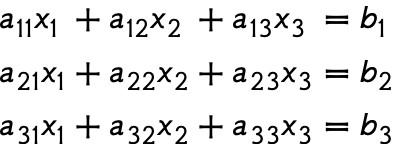

wird zu

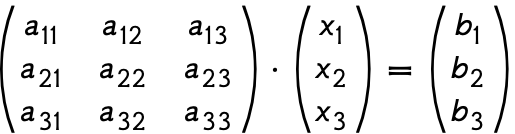.

Angenommen, wir haben unser lineares Gleichungssystem auf diese Form gebracht. Dann können wir recht einfach von MATLAB die Lösung berechnen lassen. Die Idee, die dahinter steckt ist, die Inverse der Matrix $A$, also $A^{-1}$ zu benutzen, denn dann gilt

$Ax = b \Leftrightarrow x = A^{-1} b$.

Die Inverse einer quadratischen Matrix wird mit dem `inv()`-Befehl berechnet:

% lineares Gleichungssystem in Matrix-Vektor-Schreibweise
A = [1, -3, 2; -5, -4, 2; 2, 1, 0]
b = [-5; -6; 1]

% Berechnung der Lösung mit der inversen Matrix
x = inv(A) * b



% Kontrolle
A * x

#### Mini-Übung:

Lösen Sie das lineare Gleichungssystem

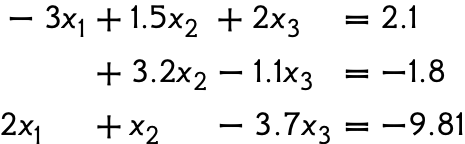

mit MATLAB.

% Hier Ihr Code



# Übungsaufgaben zur Vertiefung

#### Aufgabe 11.1

Schreiben Sie ein MATLAB-Programm, dass das Spiel Stein - Schere -Papier implementiert.

Ein Spieler oder eine Spielerin darf zuerst aus den Möglichkeiten Stein, Schere und Papier wählen. Verwenden Sie dazu eine Drop-Down-Liste. Danach wählt der Computer zufällig aus den drei Möglichkeiten. Geben Sie aus, wer gewonnen hat oder ob es ein Unentschieden gibt. Zur Erinnerung: Papier gewinnt gegen Stein, Stein gewinnt gegen Schere und Schere gewinnt gegen Papier.

% Hier Ihr Code


#### Aufgabe 11.2

Bearbeiten Sie das Quiz zur Fehlersuche in campUAS.